## ARX Model

% Create data for ARX Model

s = tf('s');
sys = 2 * exp(-2*s)/ (10*s +1)

sys =
 
                 2
  exp(-2*s) * --------
              10 s + 1
 
Continuous-time transfer function.
Model Properties


Ts = 1; 
Tend = 120;
nxmax = 10;
t = (0:Ts:Tend+nxmax);
u = ones(size(t));
u(1:nxmax) = 0;

y = lsim(sys,u,t)

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



u = u(:); y = y(:);

data = iddata(y,u,Ts, 'Name', 'FOPDT step')

data =

Time domain data set with 131 samples.
Sample time: 1 seconds                 
Name: FOPDT step                       
                                       
Outputs      Unit (if specified)       
   y1                                  
                                       
Inputs       Unit (if specified)       
   u1                                  
                                       
Data Properties


m32 = arx(data,[3,2,1]);
present(m32)

m32 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                            
  A(z) = 1 - 1.405 (+/- 0.07809) z^-1 + 0.4524 (+/- 0.1311) z^-2 + 1.586e-16 (+/- 0.06409) z^-3
                                                                                               
  B(z) = -3.9e-17 (+/- 0.01213) z^-1 + 0.09516 (+/- 0.01486) z^-2                              
                                                                                               
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=2   nk=1
   Number of free coefficients: 5
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using ARX on time domain data "FOPDT step".
Fit to estimation data: 98.18% (prediction focus)    
FPE: 0.0001562, MSE: 0.0001383                       
More information in model's "Report" property.
 


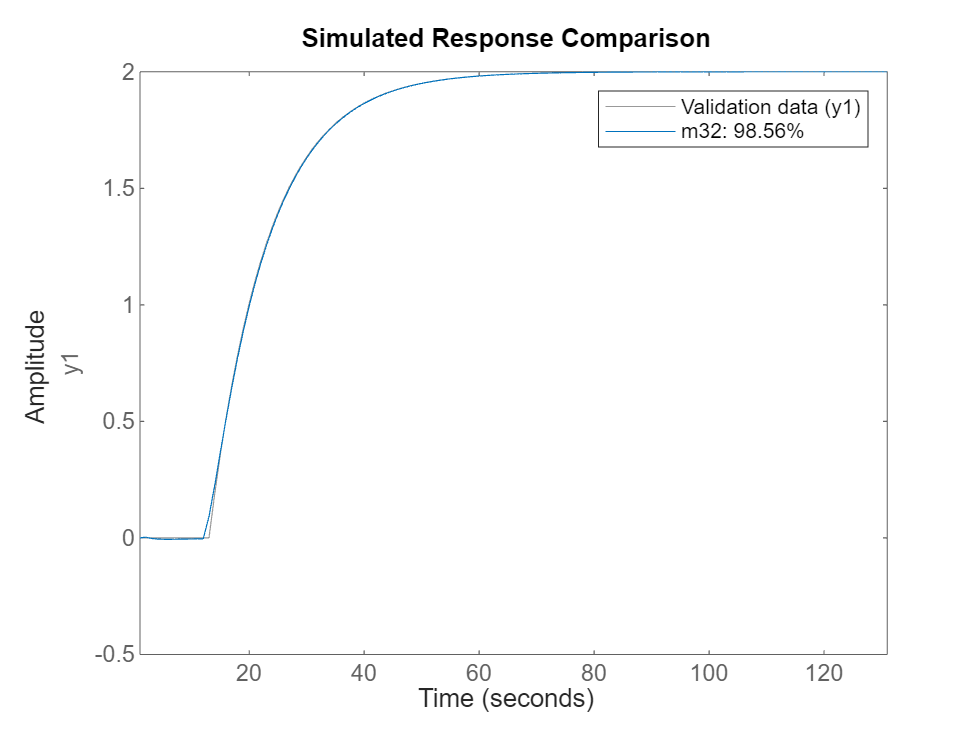

compare(data,m32)

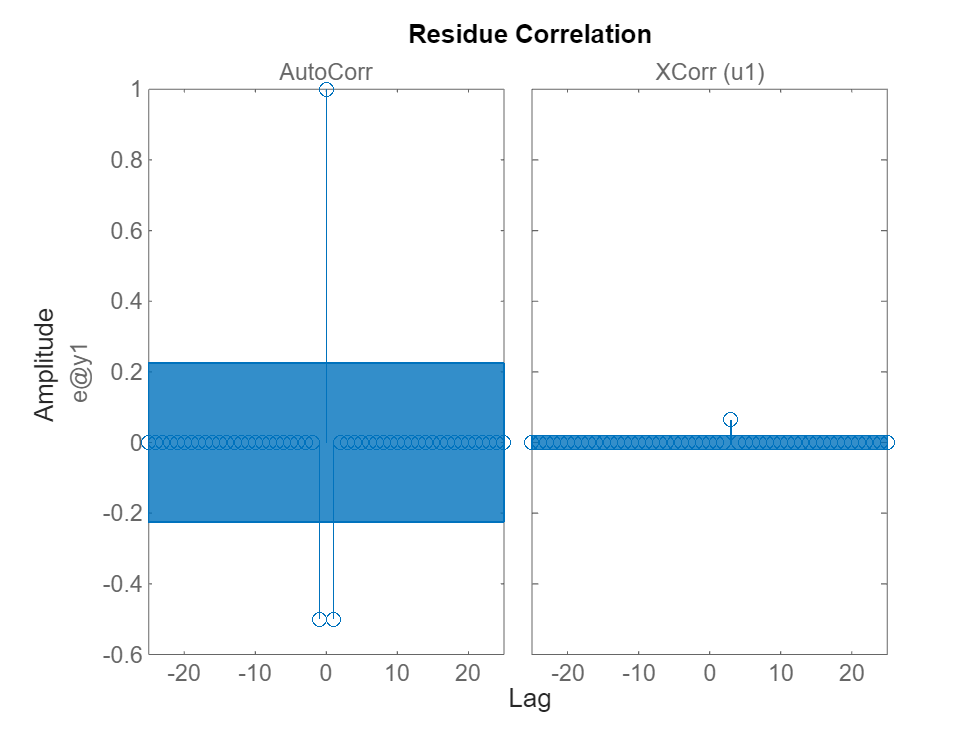

resid(data,m32)

m32

m32 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)   
  A(z) = 1 - 1.405 z^-1 + 0.4524 z^-2 + 1.586e-16 z^-3
                                                      
  B(z) = -3.9e-17 z^-1 + 0.09516 z^-2                 
                                                      
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=2   nk=1
   Number of free coefficients: 5
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using ARX on time domain data "FOPDT step".
Fit to estimation data: 98.18% (prediction focus)    
FPE: 0.0001562, MSE: 0.0001383                       
 
Model Properties


% Grid search

NN = struc(1:4, 1:3, 2);
V = arxstruc(data,data,NN);
orders = selstruc(V,0); 
m = arx(data,orders)

m =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 - 0.9048 z^-1                           
                                                   
  B(z) = 2.109e-17 z^-2 + 0.1903 z^-3              
                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=1   nb=2   nk=2
   Number of free coefficients: 3
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using ARX on time domain data "FOPDT step".
Fit to estimation data: 100% (prediction focus)      
FPE: 1.78e-31, MSE: 1.649e-31                        
 
Model Properties


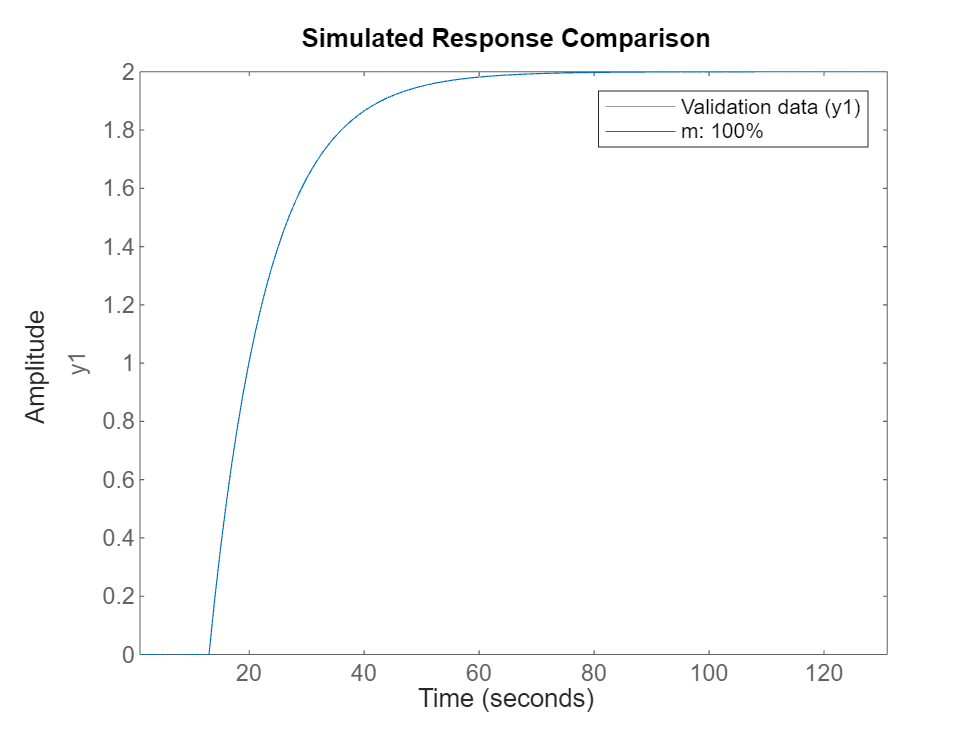

compare(data,m)

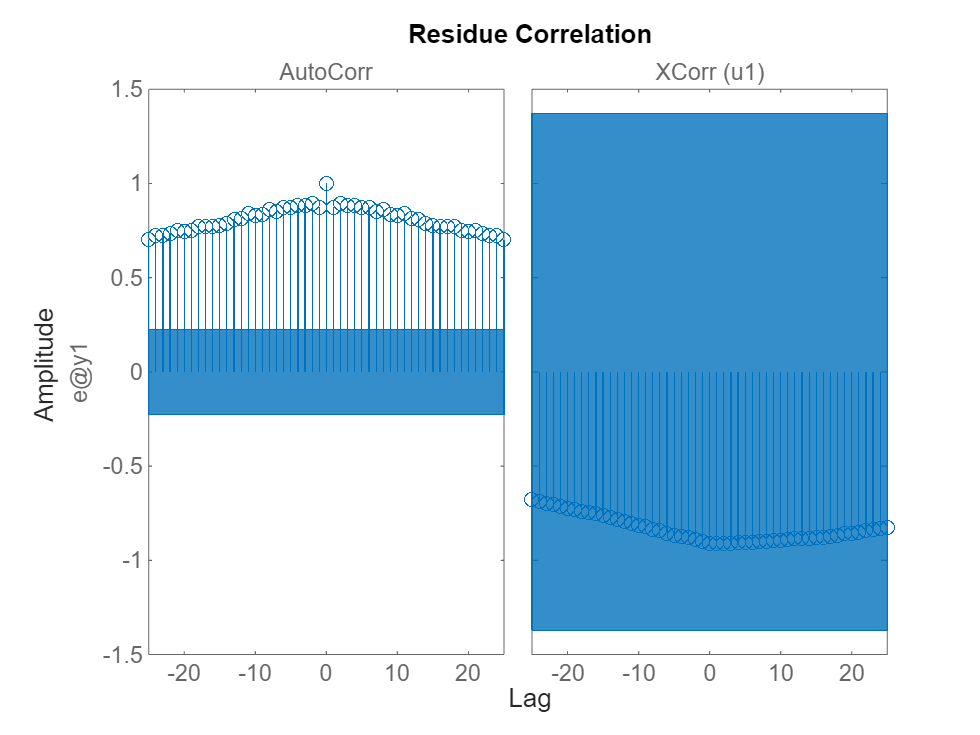

resid(data,m)